clear all ; close all ; clf ; clc; format short ;

sales = readtable('yearly_sales.csv');
class(sales)

ans = 'table'

sales.Properties

ans =   TableProperties with properties:

             Description: ''
                UserData: []
          DimensionNames: {'Row'  'Variables'}
           VariableNames: {'cust_id'  'sales_total'  'num_of_orders'  'gender'}
    VariableDescriptions: {}
           VariableUnits: {}
      VariableContinuity: []
                RowNames: {}
        CustomProperties: No custom properties are set.
      Use addprop and rmprop to modify CustomProperties.


head(sales)

     cust_id      sales_total    num_of_orders    gender
    __________    ___________    _____________    ______

         1e+05      800.64             3          {'F'} 
         1e+05      217.53             3          {'F'} 
         1e+05       74.58             2          {'M'} 
         1e+05       498.6             3          {'M'} 
         1e+05      723.11             4          {'F'} 
    1.0001e+05       69.43             2          {'F'} 
    1.0001e+05       40.15             2          {'M'} 
    1.0001e+05       58.61             2          {'M'} 



size(sales)

ans =        10000           4


sales.Properties.VariableNames

ans = 1×4 cell array
    {'cust_id'}    {'sales_total'}    {'num_of_orders'}    {'gender'}


## Stats of the data

s=summary(sales)

s = struct with fields:
          cust_id: [1×1 struct]
      sales_total: [1×1 struct]
    num_of_orders: [1×1 struct]
           gender: [1×1 struct]


s.cust_id

ans = struct with fields:
           Size: [10000 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 100001
         Median: 1.0500e+05
            Max: 110000
     NumMissing: 0


s.sales_total

ans = struct with fields:
           Size: [10000 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 30.0200
         Median: 151.6500
            Max: 7.6061e+03
     NumMissing: 0


s.num_of_orders

ans = struct with fields:
           Size: [10000 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 1
         Median: 2
            Max: 22
     NumMissing: 0



groupsummary(sales,'gender','mean')

ans = 2×5 table
    gender    GroupCount    mean_cust_id    mean_sales_total    mean_num_of_orders
    ______    __________    ____________    ________________    __________________

    {'F'}        5035        1.0508e+05          247.74               2.4131      
    {'M'}        4965        1.0492e+05          251.19               2.4431      


groupsummary(sales,'gender','std')

ans = 2×5 table
    gender    GroupCount    std_cust_id    std_sales_total    std_num_of_orders
    ______    __________    ___________    _______________    _________________

    {'F'}        5035           2880           334.77              1.4216      
    {'M'}        4965         2892.1           302.29              1.4607      


groupsummary(sales,'gender','var')

ans = 2×5 table
    gender    GroupCount    var_cust_id    var_sales_total    var_num_of_orders
    ______    __________    ___________    _______________    _________________

    {'F'}        5035       8.2946e+06       1.1207e+05            2.0208      
    {'M'}        4965       8.3644e+06            91382            2.1336      



gs=groupsummary(sales,'gender','all')

gs = 2×35 table
    gender    GroupCount    mean_cust_id    sum_cust_id    min_cust_id    max_cust_id    range_cust_id    median_cust_id    mode_cust_id    var_cust_id    std_cust_id    nummissing_cust_id    nnz_cust_id    mean_sales_total    sum_sales_total    min_sales_total    max_sales_total    range_sales_total    median_sales_total    mode_sales_total    var_sales_total    std_sales_total    nummissing_sales_total    nnz_sales_total    mean_num_of_orders    sum_num_of_orders    min_num_of_orders    max_num_of_orders


gs.range_sales_total

ans = 1.0e+03 *

    7.5761
    4.0169



quantile(sales.sales_total,[0 0.25 0.5 0.75 1])

ans = 1.0e+03 *

    0.0300    0.0803    0.1517    0.2955    7.6061


quantile(sales.num_of_orders,[0 0.25 0.5 0.75 1])

ans =      1     2     2     3    22


## Histograms of data

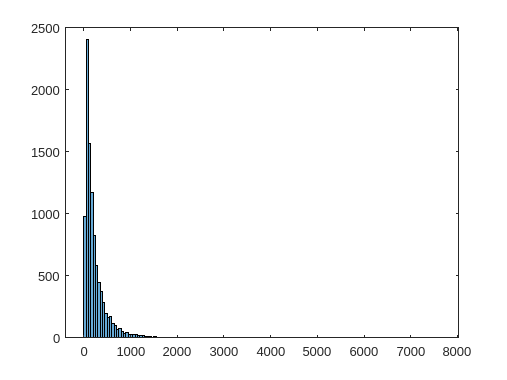

clf
figure(1)
histogram(sales.sales_total)

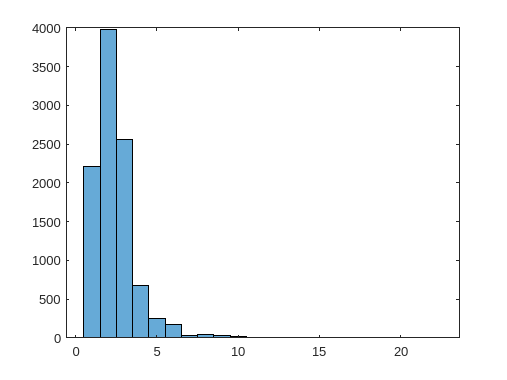

histogram(sales.num_of_orders)


figure(2)
hold on
h1=histogram(sales.sales_total(find(strcmp(sales.gender,'M'))))

h1 =   Histogram with properties:

             Data: [4965×1 double]
           Values: [499 1157 765 593 404 290 238 184 146 103 82 93 57 50 30 35 28 23 23 19 16 17 10 12 12 12 5 6 5 3 3 3 2 2 2 4 2 2 3 1 2 4 1 2 3 0 1 2 0 0 1 1 0 0 0 1 0 1 0 0 0 0 0 0 0 2 0 0 0 0 1 0 0 0 0 0 0 1 0 0 1]
          NumBins: 81
         BinEdges: [0 50 100 150 200 250 300 350 400 450 500 550 600 650 700 750 800 850 900 950 1000 1050 1100 1150 1200 1250 1300 1350 1400 1450 1500 1550 1600 1650 1700 1750 1800 1850 1900 1950 2000 2050 2100 2150 2200 2250 2300 2350 2400 2450 … ]
         BinWidth: 50
        BinLimits: [0 4050]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all proper

h2=histogram(sales.sales_total(find(strcmp(sales.gender,'F'))))

h2 =   Histogram with properties:

             Data: [5035×1 double]
           Values: [477 1249 807 584 424 298 213 190 138 92 80 77 58 52 35 44 24 14 21 13 16 11 19 9 7 10 10 3 5 2 7 2 6 2 3 4 0 1 1 1 4 0 1 0 1 0 1 5 1 3 0 1 0 1 0 0 0 0 0 0 1 0 0 0 0 1 0 0 0 1 0 0 1 0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
          NumBins: 153
         BinEdges: [0 50 100 150 200 250 300 350 400 450 500 550 600 650 700 750 800 850 900 950 1000 1050 1100 1150 1200 1250 1300 1350 1400 1450 1500 1550 1600 1650 1700 1750 1800 1850 1900 1950 2000 2050 2100 2150 2200 2250 2300 2350 2400 2450 … ]
         BinWidth: 50
        BinLimits: [0 7650]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

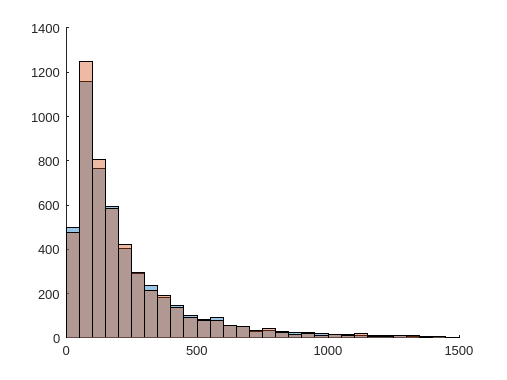

set(h1,'facealpha',0.4);
set(h2,'facealpha',0.4);
xlim([0 1500])
hold off


figure(3)
hold on
h1=histogram(sales.num_of_orders(find(strcmp(sales.gender,'M'))))

h1 =   Histogram with properties:

             Data: [4965×1 double]
           Values: [1101 1960 1268 340 114 98 19 22 21 8 3 1 1 0 1 1 6 1]
          NumBins: 18
         BinEdges: [0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000 9.5000 10.5000 11.5000 12.5000 13.5000 14.5000 15.5000 16.5000 17.5000 18.5000]
         BinWidth: 1
        BinLimits: [0.5000 18.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h2=histogram(sales.num_of_orders(find(strcmp(sales.gender,'F'))))

h2 =   Histogram with properties:

             Data: [5035×1 double]
           Values: [1111 2023 1288 331 140 70 17 20 16 9 1 1 0 0 0 1 2 2 0 1 1 1]
          NumBins: 22
         BinEdges: [0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000 9.5000 10.5000 11.5000 12.5000 13.5000 14.5000 15.5000 16.5000 17.5000 18.5000 19.5000 20.5000 21.5000 22.5000]
         BinWidth: 1
        BinLimits: [0.5000 22.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


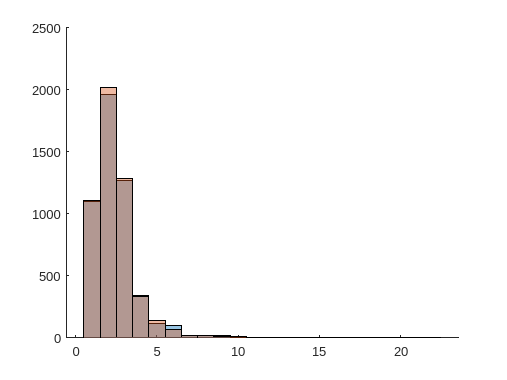

set(h1,'facealpha',0.4);
set(h2,'facealpha',0.4);
hold off

## Scatter and adjustment

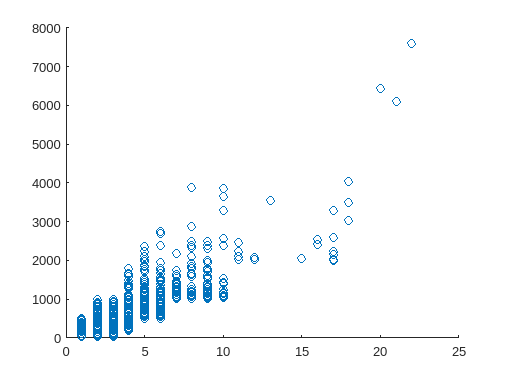

figure(4)
hold on
scatter(sales.num_of_orders,sales.sales_total)
hold off


[f,gof,output] = fit(sales.num_of_orders,sales.sales_total,"poly1")

f =      Linear model Poly1:
     f(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       166.2  (163.4, 169.1)
       p2 =      -154.1  (-162.2, -146)

gof = struct with fields:
           sse: 4.4408e+08
       rsquare: 0.5637
           dfe: 9998
    adjrsquare: 0.5637
          rmse: 210.7525


output = struct with fields:
        numobs: 10000
      numparam: 2
     residuals: [10000×1 double]
      Jacobian: [10000×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


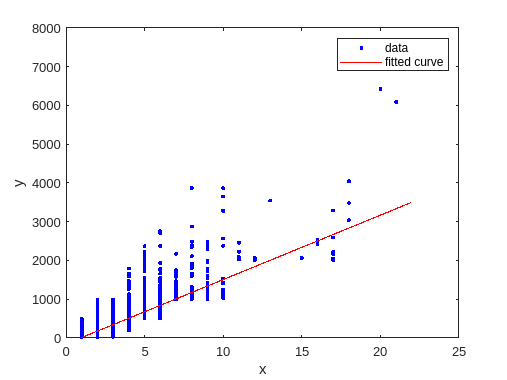

plot(f,sales.num_of_orders,sales.sales_total)

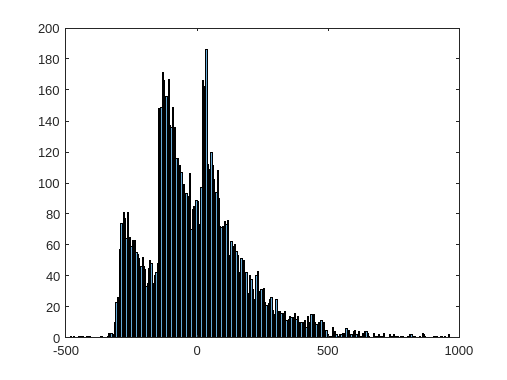


histogram(output.residuals,1000)
xlim([-500 1000])

### New variables generation

sales.ave = sales.sales_total./sales.num_of_orders;
head(sales)

     cust_id      sales_total    num_of_orders    gender     ave  
    __________    ___________    _____________    ______    ______

         1e+05      800.64             3          {'F'}     266.88
         1e+05      217.53             3          {'F'}      72.51
         1e+05       74.58             2          {'M'}      37.29
         1e+05       498.6             3          {'M'}      166.2
         1e+05      723.11             4          {'F'}     180.78
    1.0001e+05       69.43             2          {'F'}     34.715
    1.0001e+05       40.15             2          {'M'}     20.075
    1.0001e+05       58.61             2          {'M'}     29.305



pdwei = fitdist(sales.ave, "Weibull")

pdwei =   WeibullDistribution

  Weibull distribution
    A = 109.933   [108.286, 111.605]
    B = 1.37684   [1.3571, 1.39687]


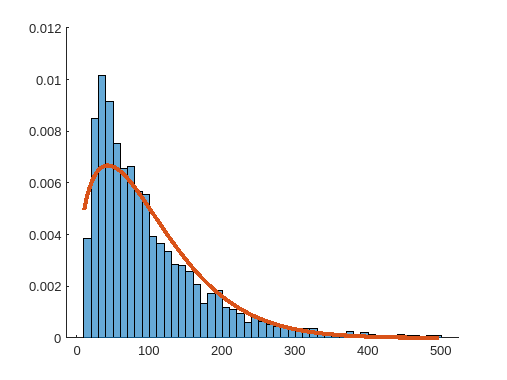


figure(5)
clf
hold on
histogram(sales.ave, "Normalization", "pdf")
xx=linspace(min(sales.ave),max(sales.ave),200);
pdweipdf=pdf(pdwei,xx);
plot(xx,pdweipdf,'LineWidth',3)
hold off

## Contingence Tables

spender=repelem({'medium'},size(sales,1));
spender(sales.sales_total<100) = repelem({'small'},sum(sales.sales_total<100));
spender(sales.sales_total>=500) = repelem({'big'},sum(sales.sales_total>=500));
sales.spender=spender';

[conttble,chi2,p,labels] = crosstab(sales.gender,sales.spender)

conttble =          563        2746        1726
         586        2723        1656


chi2 = 1.5160

p = 0.4686

labels = 3×2 cell array
    {'F'       }    {'big'   }
    {'M'       }    {'medium'}
    {0×0 double}    {'small' }


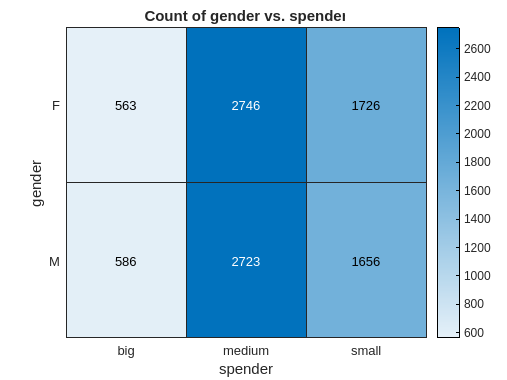


heatmap(sales,'spender','gender')


statsbygender = grpstats(sales, 'gender', {'min','max','mean','std'},'DataVars','sales_total')

statsbygender = 2×6 table
         gender    GroupCount    min_sales_total    max_sales_total    mean_sales_total    std_sales_total
         ______    __________    _______________    _______________    ________________    _______________

    F    {'F'}        5035            30.02             7606.1              247.74             334.77     
    M    {'M'}        4965            30.03             4046.9              251.19             302.29     



statsbyspender = grpstats(sales, 'spender', {'min','max','mean','std'},'DataVars','sales_total')

statsbyspender = 3×6 table
               spender      GroupCount    min_sales_total    max_sales_total    mean_sales_total    std_sales_total
              __________    __________    _______________    _______________    ________________    _______________

    big       {'big'   }       1149            500.1             7606.1              897.38              558.5     
    medium    {'medium'}       5469           100.01             499.93              227.73             102.78     
    small     {'small' }       3382            30.02              99.98               64.47             19.738     



[mean(sales.sales_total) median(sales.sales_total) mode(sales.sales_total)]

ans =   249.4557  151.6500   77.7500


iqr(sales.sales_total)

ans = 215.2300

[mean(sales.num_of_orders) median(sales.num_of_orders) mode(sales.num_of_orders)]

ans =     2.4280    2.0000    2.0000


iqr(sales.num_of_orders)

ans = 1


corrcoef(sales.num_of_orders, sales.sales_total)

ans =     1.0000    0.7508
    0.7508    1.0000


cov(sales.num_of_orders, sales.sales_total)

ans = 1.0e+05 *

    0.0000    0.0035
    0.0035    1.0179


### Data sample generation for adjustment

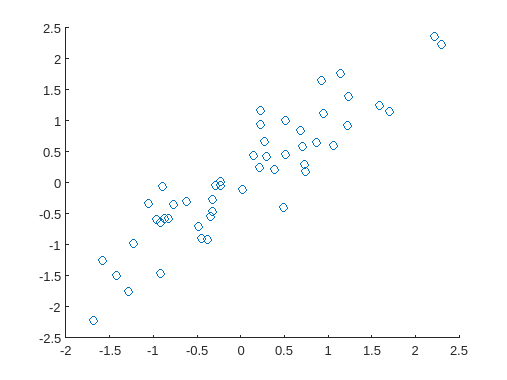

x=randn(50,1);
y=x+randn(50,1)*0.5;
scatter(x,y)


[fitobject, gof, output] = fit(x,y,'poly1')

fitobject =      Linear model Poly1:
     fitobject(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.9414  (0.8167, 1.066)
       p2 =      0.0554  (-0.06369, 0.1745)

gof = struct with fields:
           sse: 8.3834
       rsquare: 0.8276
           dfe: 48
    adjrsquare: 0.8240
          rmse: 0.4179


output = struct with fields:
        numobs: 50
      numparam: 2
     residuals: [50×1 double]
      Jacobian: [50×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


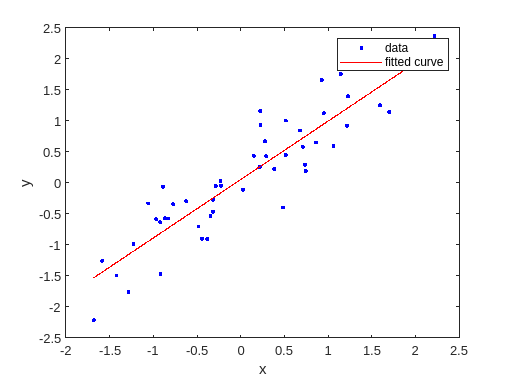

plot(fitobject,x,y)

## Anscombe's Quartet

x1=[10 8 13 9 11 14 6 4 12 7 5]';
x2=x1;
x3=x1;
x4=[8 8 8 8 8 8 8 19 8 8 8]';

y1=[8.04 6.95 7.58 8.81 8.33 9.96 7.24 4.26 10.84 4.82 5.68]';
y2=[9.14 8.14 8.74 8.77 9.26 8.1 6.13 3.1 9.13 7.26 4.74]';
y3=[7.46 6.77 12.74 7.11 7.81 8.84 6.08 5.39 8.15 6.42 5.73]';
y4=[6.58 5.76 7.71 8.84 8.47 7.04 5.25 12.5 5.56 7.91 6.89]';

[f1,gof1,out1] = fit(x1,y1,'poly1')

f1 =      Linear model Poly1:
     f1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.5001  (0.2334, 0.7668)
       p2 =           3  (0.4557, 5.544)

gof1 = struct with fields:
           sse: 13.7627
       rsquare: 0.6665
           dfe: 9
    adjrsquare: 0.6295
          rmse: 1.2366


out1 = struct with fields:
        numobs: 11
      numparam: 2
     residuals: [11×1 double]
      Jacobian: [11×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


[f2,gof2,out2] = fit(x2,y2,'poly1')

f2 =      Linear model Poly1:
     f2(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =         0.5  (0.2331, 0.7669)
       p2 =       3.001  (0.4553, 5.547)

gof2 = struct with fields:
           sse: 13.7763
       rsquare: 0.6662
           dfe: 9
    adjrsquare: 0.6292
          rmse: 1.2372


out2 = struct with fields:
        numobs: 11
      numparam: 2
     residuals: [11×1 double]
      Jacobian: [11×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


[f3,gof3,out3] = fit(x3,y3,'poly1')

f3 =      Linear model Poly1:
     f3(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4997  (0.2331, 0.7664)
       p2 =       3.002  (0.4587, 5.546)

gof3 = struct with fields:
           sse: 13.7562
       rsquare: 0.6663
           dfe: 9
    adjrsquare: 0.6292
          rmse: 1.2363


out3 = struct with fields:
        numobs: 11
      numparam: 2
     residuals: [11×1 double]
      Jacobian: [11×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


[f4,gof4,out4] = fit(x4,y4,'poly1')

f4 =      Linear model Poly1:
     f4(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      0.4999  (0.2334, 0.7664)
       p2 =       3.002  (0.4592, 5.544)

gof4 = struct with fields:
           sse: 13.7425
       rsquare: 0.6667
           dfe: 9
    adjrsquare: 0.6297
          rmse: 1.2357


out4 = struct with fields:
        numobs: 11
      numparam: 2
     residuals: [11×1 double]
      Jacobian: [11×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1



figure(31)
opts.MarkerSize=8

opts = struct with fields:
    MarkerSize: 8


opts.MarkerEdgeColor='red'

opts = struct with fields:
         MarkerSize: 8
    MarkerEdgeColor: 'red'


opts.MarkerFaceColor='red'

opts = struct with fields:
         MarkerSize: 8
    MarkerEdgeColor: 'red'
    MarkerFaceColor: 'red'


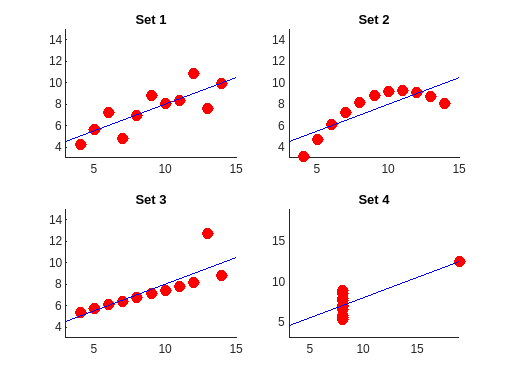

clf
subplot(2,2,1);
hold on
plot(x1,y1,'o',opts)
plot([3,15],[3*f1.p1+f1.p2,15*f1.p1+f1.p2],'b')
xlim([3 15]); ylim([3 15])
title('Set 1')
hold off
subplot(2,2,2);
hold on
plot(x2,y2,'o',opts)
plot([3,15],[3*f2.p1+f2.p2,15*f2.p1+f2.p2],'b')
xlim([3 15]); ylim([3 15])
title('Set 2')
hold off
subplot(2,2,3);
hold on
plot(x3,y3,'o',opts)
plot([3,15],[3*f3.p1+f3.p2,15*f3.p1+f3.p2],'b')
xlim([3 15]); ylim([3 15])
title('Set 3')
hold off
subplot(2,2,4);
hold on
plot(x4,y4,'o',opts)
plot([3,19],[3*f4.p1+f4.p2,19*f4.p1+f4.p2],'b')
xlim([3 19]); ylim([3 19])
title('Set 4')
hold off

## Datos sucios

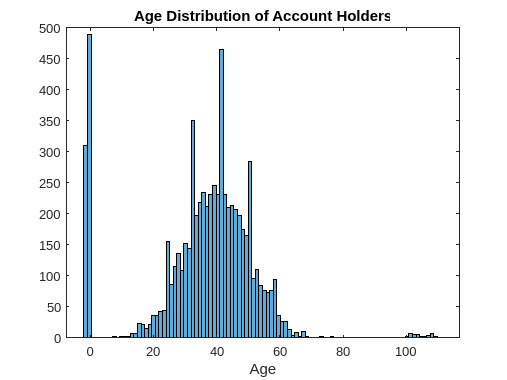

age = randn(6000,1)*10+40;
age=[age; unifrnd(-2,0,400,1); zeros(400,1); unifrnd(100,110,40,1)];
age=round(age);
clf
histogram(age,100)
title("Age Distribution of Account Holders")
xlabel("Age")

ylab=("Frequency")

ylab = "Frequency"


x=[1, 2, 3, NaN, 4]

x =      1     2     3   NaN     4


isnan(x)

ans = 1×5 logical array
   0   0   0   1   0


mean(x)

ans = NaN

nanmean(x)

ans = 2.5000


Tbl=table([1;2;3],[10;20;NaN])

Tbl = 3×2 table
    Var1    Var2
    ____    ____

     1       10 
     2       20 
     3      NaN 


arr=table2array(Tbl)

arr =      1    10
     2    20
     3   NaN


mean(arr)

ans =      2   NaN


nanmean(arr)

ans =      2    15



Tble2=rmmissing(Tbl)

Tble2 = 2×2 table
    Var1    Var2
    ____    ____

     1       10 
     2       20 


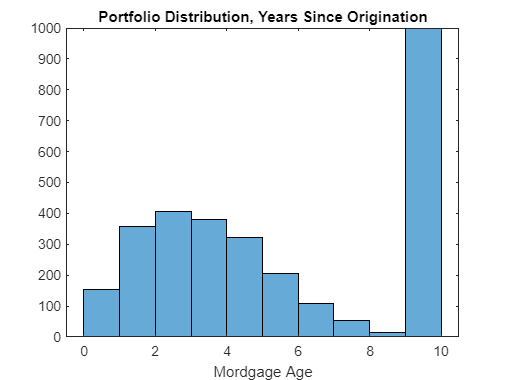

mortgage=betarnd(2,4,2000,1)*10;
mortgage=[mortgage; ones(1000,1)*10];

histogram(mortgage,10)
xlabel("Mortgage Age")
title("Portfolio Distribution, Years Since Origination")

income=lognrnd(4,0.7,4000,1);
income=1000*income;
mean(income)

ans = 6.9283e+04


quantile(income,[0 0.25 0.5 0.75 1.])

ans = 1.0e+05 *

    0.0428    0.3350    0.5391    0.8568    7.1333


std(income)

ans = 5.5697e+04

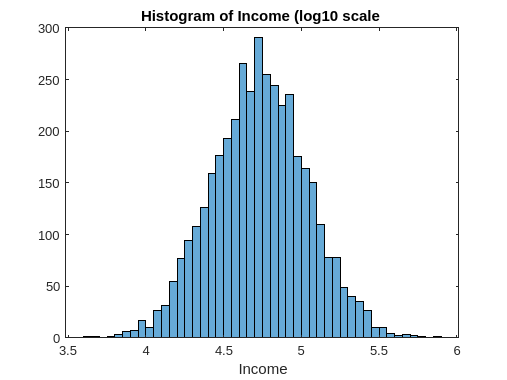


clf
histogram(log10(income))
xlabel("Income")
title("Histogram of Income (log10 scale)")